# `General Equilibrium `

## `Learning Goals `

- `Gain a fundamental understanding of market equilibrium`

- `See how linear algebra can be used to simplify complex systems of real-world effects`

- `Review the Gauss-Jordan reduction method, augmented matrices, and coefficient matrices`

## `Background Information`

#### `What is Market Equilibrium?`

`When the quantity supplied for a good is equal to the quantity demanded for the same good, a market is said to be in ``equilibrium``. In a market, price adjusts to move the market closer to equilibrium; we call price the ``market-clearing mechanism.`

`To find market equilibrium, economists model the interactions between supply and demand. Supply is modeled as an upward-sloping line called the supply curve, while demand is represented by a downward-sloping line called the demand curve. The laws of supply and demand inform the slopes of these curves. The ``Law of Supply`` states that as the price of a good rises, producers are willing to supply more, causing the supply curve to be upward sloping. The ``Law of Demand`` asserts that as the price of a good rises, consumers will buy fewer units, giving the demand curve a negative slope.`

#### `What is General Equilibrium?`

`In practice, markets are rarely isolated from one another. Prices found in one market have far-reaching impacts across many different markets. ``General equilibrium`` is when all these interconnected markets within an economy are simultaneously found to be in equilibrium. General equilibrium is more of a theoretical concept, as it relies on assumptions that can not realistically be upheld in the imperfect markets of our world. However, general equilibrium serves as a theoretical baseline to understand how interconnected markets coordinate. Moreover, Computable General Equilibrium (CGE) models are used to approximate policy impacts and general market fluctuations.`

## `Linear Algebra and Finding Equilibrium Price`

`In a given market, we have two equations: one gives the quantity supplied, and the other gives the quantity demanded at a given market price. To find the equilibrium price in a single market, we assume quantity demanded is equal to quantity supplied and then solve for price. But to determine general equilibrium, we need to determine multiple different equilibrium prices, each dependent upon the others, across many markets. This gives us a complex system of linear equations with the same number of prices, independent variables, as markets.`

`To solve this system of equations for a set of equilibrium prices across multiple markets, we will use some fundamental linear algebra techniques. We will see how ``coefficient matrices``, ``constant vectors``, and ``augmented matrices`` are used to represent an intricate system of linear equations in the form of a comparatively simple matrix. Then we’ll see how this matrix representing our linear system can be operated on using ``elementary row operations`` to obtain clear solutions. In this example, the ``Gauss-Jordan reduction method`` will be used to find general equilibrium.`

## `Partial Equilibrium Example:`

`Suppose one market has the following inverse demand and supply curves, where `$Q_D$` gives the quantity demanded at a given price P, and `$Q_S$` gives the quantity supplied at a given P.`

`Take,`


$$Q_D =-P+7\;,{\;Q}_S =4P-4$$


`For MATLAB we'll write, `

D= @(p) -1*p + 7;
S= @(p) 4*p - 4 ;

`Plotting these functions, we can find their intersection graphically.`

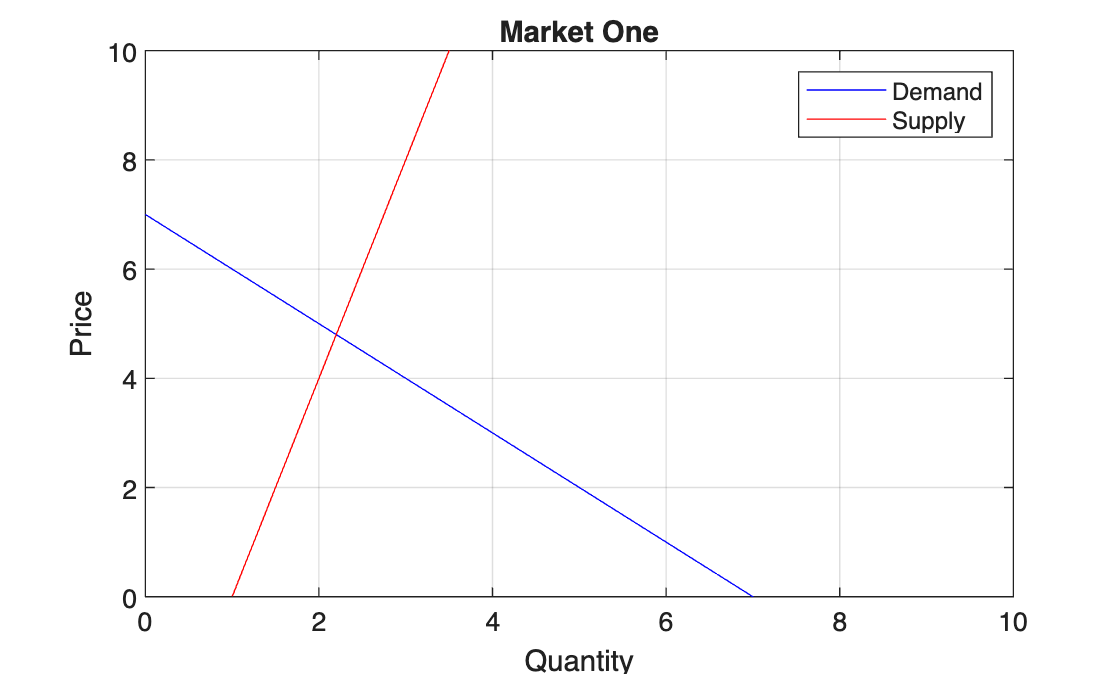

fplot(D,[0,10],'blue')
grid on
title('Market One');
xlabel('Quantity');
ylabel('Price');
ylim([0, 10]);
hold on;
fplot(S,[0,10],'red')
legend('Demand', 'Supply')
hold off;

`The point where the supply and demand curves in the graph above intersect represents market equilibrium. The price at this point is the equilibrium price, which subsequently yields the equilibrium quantity.`

## `Simplified General Equilibrium Model`

`Modeling general equilibrium is much like the single market model. The same underlying economic laws apply in each market, but now the prices and quantities found in one market are directly affected by the prices and quantities found in another.`

`EXAMPLE:`

`Suppose market A is the market for fish, market B is the market for steak, and market C is the market for olives. Take the supply and demand equations of these three interdependent markets. Note that the quantity demanded of any given good is dependent upon the price of at least one other good sold in a different market. At what set of prices are the quantities supplied equal to the quantities demanded for each good across all three markets? Let price be measured in dollars and quantity in pounds.`

`Each market is characterized by the following sets of equations: `

`Market A: `


$$\left\lbrace \begin{array}{ll}
Q_{D_A } =P_A -2P_B +10 & \\
Q_{S_A } =2P_A  & 
\end{array}\right.$$


`Market B:`


$$\left\lbrace \begin{array}{ll}
Q_{D_B } =P_B -2P_C +11 & \\
Q_{S_B } =P_A +P_B +P_C  & 
\end{array}\right.$$


`Market C:`


$$\left\lbrace \begin{array}{ll}
Q_{D_C } =P_C -2P_B +24 & \\
Q_{S_C } =3P_C +8 & 
\end{array}\right.$$


`By setting the supply and demand functions equal in each market, we find a system of three equations of three variables. Solving this system will give us the equilibrium price observed in each market: `$P_A^* ,\;P_B^* ,{\;P}_C^*$`. `

`We have, `


$$P_A +{2P}_B =10$$



$$P_A +3P_C =11$$



$$2P_B +2P_C =16$$


`Now we can solve this system using some basic linear algebra techniques.`

`First, construct the ``coefficient matrix`` for the linear system above. Stored within this coefficient matrix are, as you might expect, the coefficients of the independent variables of a corresponding linear system. In this case, the columns of A hold the coefficients to `$P_A {,\;P}_B$`, and `$P_C$`, respectively, while the entries in each row correspond strictly to a single equation in the system.`

A=[1 2 0;1 0 3;0  2 2]

A =      1     2     0
     1     0     3
     0     2     2


`Next, determine your ``constant vector``. This vector holds the output values of each of the given equations.`

b=[10;11;16]

b =     10
    11
    16


`Hence, the following construction represents our three equation linear system: `$\textrm{Ax}=b$`, where `$x=\left\lbrack \begin{array}{c}
P_A \\
P_B \\
P_c 
\end{array}\right\rbrack$`.`

`Using A and b, construct an ``augmented matrix`` representing this 3-equation system.`

Aaug = [A b]

Aaug =      1     2     0    10
     1     0     3    11
     0     2     2    16


`Now, by row reducing Aaug with the ``Gauss-Jordan Reduction Method``, or with the rref function in MATLAB, we can find our three equilibrium prices. `

R = rref(Aaug)

R =     1.0000         0         0    0.8000
         0    1.0000         0    4.6000
         0         0    1.0000    3.4000


`Therefore, the equilibrium prices are `$P_A^* =\$0\ldotp 8,{\;\;P}_B^* =\$4\ldotp 6,$` and `${\;P}_C^* =3\ldotp 4$`.`

`Plugging these values into our original supply/demand function, it does not matter which, we can find the associated equilibrium quantities,`

$Q_A^* =1\ldotp 6{,\;Q}_B^* =8\ldotp 8$`, and `$Q_C^* =13\ldotp 2$`.`

`So whenever the above list of prices is set, the quantities supplied and the quantities demanded for these three goods are equal, within their respective markets. Hence, each of the three markets in the economy is in equilibrium contemporaneously, further implying that the economy is in a state of general equilibrium when the prices `$P_A^* ,{\;P}_B^* ,$` and `$P_C^*$` are adopted.`

## `Conclusion`

`Linear algebra arms us with the tools to take complex systems and reduce them into relatively simple mathematical structures. In this case, we see how the complexity of interconnected markets can be better understood using elementary concepts from linear algebra. We took markets detailed by quantity supplied, quantity demanded, and price and, given standard economic assumptions, were able to find a point of general market equilibrium. It is in this process of first identifying and quantifying a convoluted real-world problem and then reducing it into something standard that linear algebra finds many of its applications in the real world.`